# TP 2

# Partie 1 : Covolution 

## Question 1

### Pour se familiariser avec le produit de convolution, reproduire les expériences de la page  35 et 36 de votre poly. Pour cela :

Créer une image noire dont le cercle de rayon R=20 pixels est blancs :

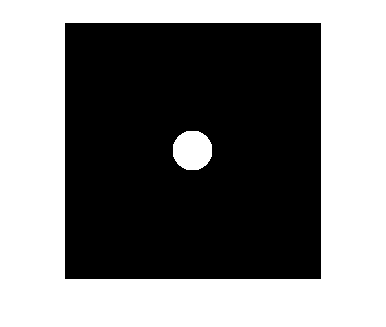

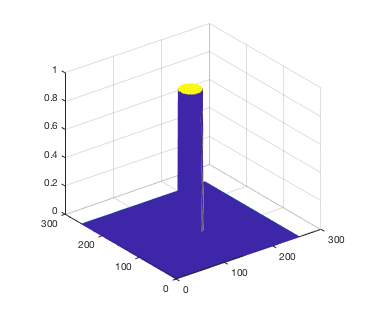

% Création de l'image noire 256x256 stockée dans Itest, utiliser la fonction zeros()
n=256;
R=20;

% Mise en blanc des pixels centraux 

% Affichage de l'image, utiliser la fonction imshow()


%Affichage de l'image en 3D avec meshz()


Créer la PSF de taille 65x65 :

Aide : En introduisant D(i,j) la distance radiale du pixel (i,j) au centre de l'image, utiliser l'expression : "PSF(i,j)=airy(0.1*D(i,j));"

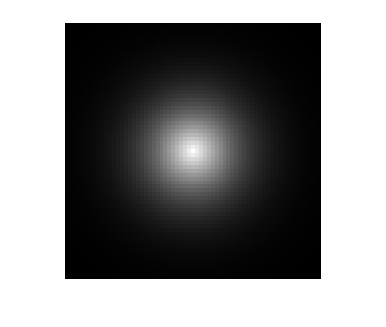

% Création image noire


% Double boucle pour créer le motif de la tache d'Airy

% Normalisation de la PSF à 1

% Affichage de la PSF avec imshox()


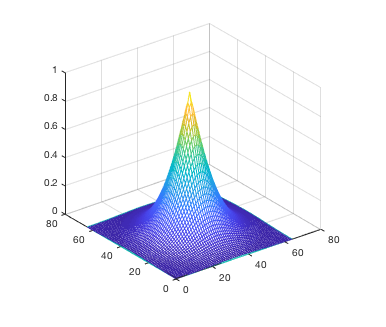

% Affichage de la PSF avec meshz()


Faire la convolution de l'image du rond blanc avec la PSF normalisée:

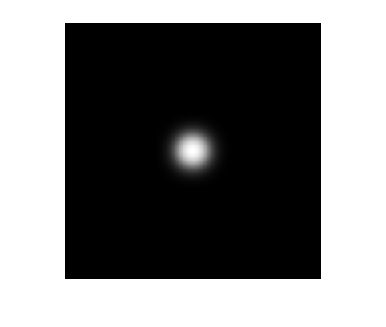

% Créer l'image convoluée avec conv2()

% Normalisation de l'image convoluée

% Afficher la convolution avec imshow()


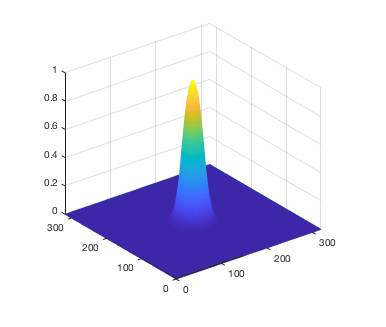

% Affichage de la PSF avec meshz()


Commenter l'image obtenue

## Question 2

### Appliquer la même convolution à l'image de Lena.  Pour cela :

Stocker l'image de Lena dans I et la convertir en nuances de gris.

Appliquer la convolution avec PSF

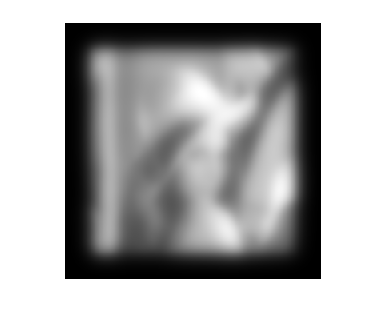

% Créer l'image convoluée avec conv2()

% Normalisation de l'image convoluée

% Afficher la convolution avec imshow()


Commenter l'image obtenue, en particulier sa taille, les effets de bords et le rendu de l'image obtenue.

## Question 3 

### Dans l'exemple précédent, la largeur de la PSF était excessivement grande, et la fenetre dans laquelle elle était inscrite également. Réitérer la convolution avec une PSF plus réelle Pour cela :

Créer une PSF de taille 9x9

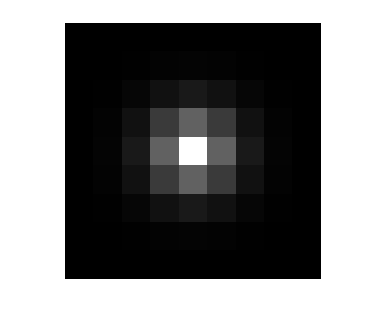

% Création image noire


% Double boucle pour créer le motif de la tache d'Airy


% Normalisation de la PSF à 1

% Affichage de la PSF avec imshox()


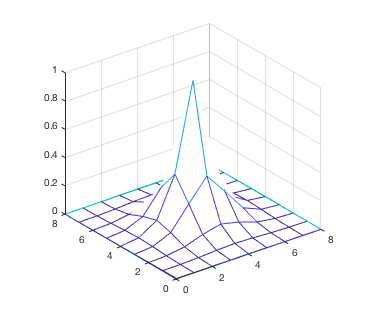

% Affichage de la PSF avec meshz()


Appliquer la convolution avec PSF

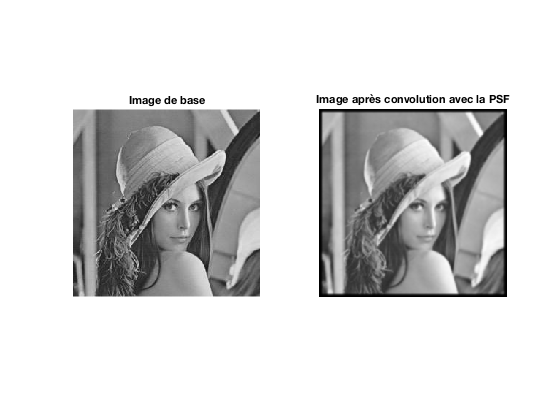

% Créer l'image convoluée avec conv2()

% Normalisation de l'image convoluée

% Afficher la convolution avec imshow(), à coté de l'image de base en noir
% et blanc à l'aide de subplot


Commenter l'image obtenue

## Question 4

### La fonction conv2 possède différents arguments "full", "valid" et "same". A quoi correspondent-ils? Pour cela :

Effectuer les convolutions de Lena avec la précédente PSF (9x9), pour chacun des 3 paramètres. Puis afficher les résultats sur une même figure à l'aide de subplot

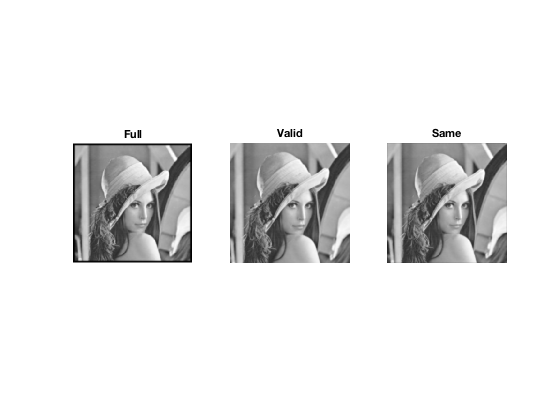

% Stockage et normalisation de la conv avec l'argument 'full'

% Stockage et normalisation de la conv avec l'argument 'valid'

% Stockage et normalisation de la conv avec l'argument 'same'

% Affichage des résultats à l'aide de imshow() et subplot


Commentez les 3 images et conclure quant aux rôles des 3 arguments de la fonction conv2.

# Partie 2 

# Corrélation 

## Question 5

### Commencer par se familiariser avec la corrélation. Pour cela :

Regarder l'aide Matlab de corr2, puis calculer la corrélation entre I et I, Itest et Itest puis entre I et Itest:

% corrélation entre I et I


ans = 1

% corrélation entre Itest et Itest


ans = 1

% corrélation entre I et Itest


ans = 0.0344

Comment évolue le coefficient de corrélation en fonction de la similarité de deux images ? 

Créer une image similaire à Itest (question1) mais dont le cercle est centré sur le pixel (200,50), stocker la dans ItestDecalee :

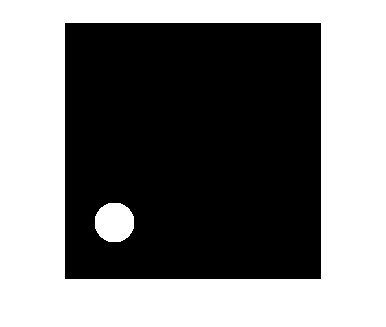

% Création de iTestDecalee


% Mise en blanc des pixels centraux 

% Affichage de l'image, utiliser la fonction imshow()


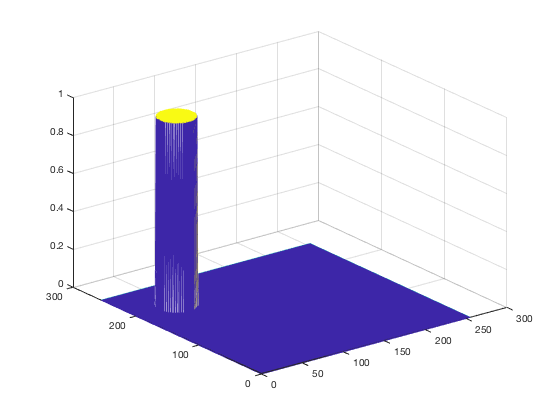

%Affichage de l'image en 3D avec meshz()


Lire l'aide de xcorr2, puis afficher les corrélation croisée de Itest et Itest, puis ItestDecale et ItestDecale et enfin Itest et ItestDecalee :

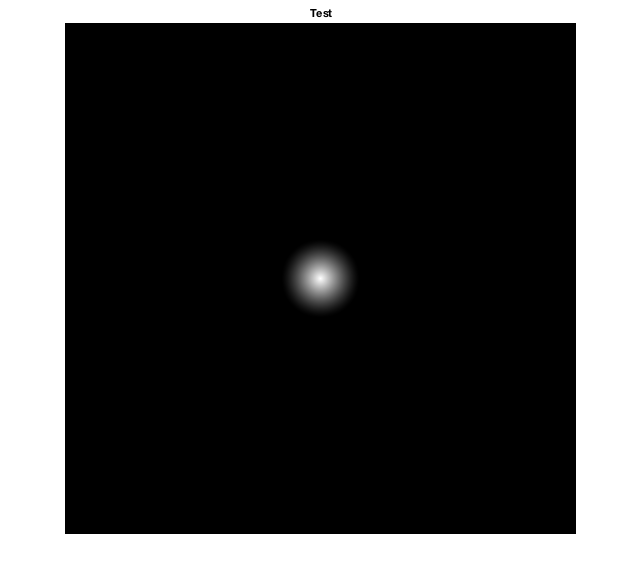

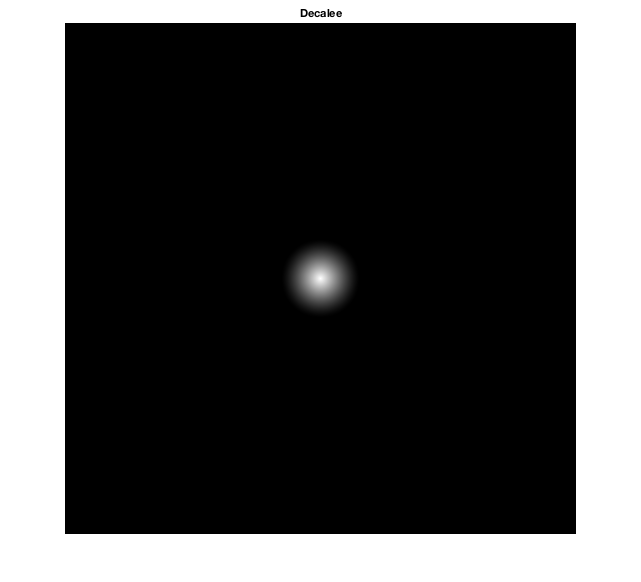

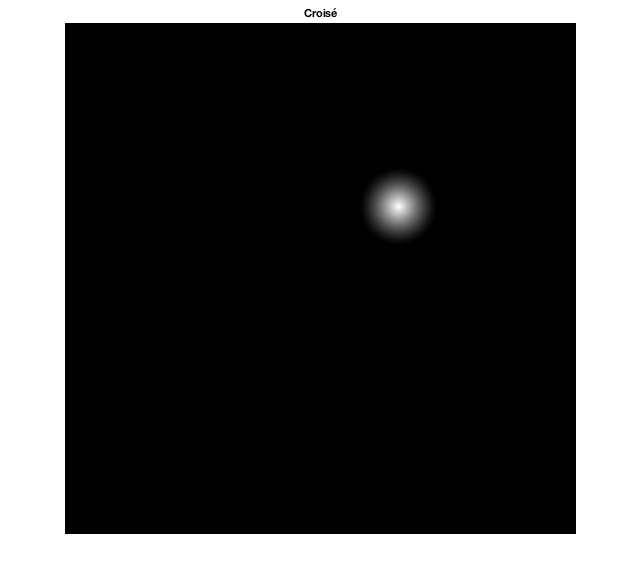

% Calcul de la corrélation croisée de Itest et Itest à l'aide de xcorr(2),

% Calcul de la corrélation croisée de ItestDecalee et ItestDecale à l'aide de xcorr(2)

% Calcul de la corrélation croisée de Itest et ItestDecale à l'aide de xcorr(2)


%Normalisation des 3 matrices



% Affichage des résultats avec imshow()


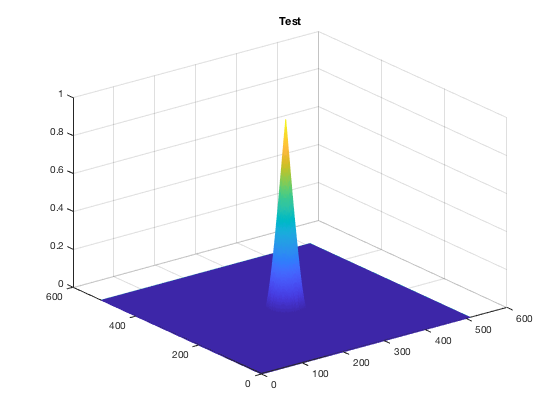

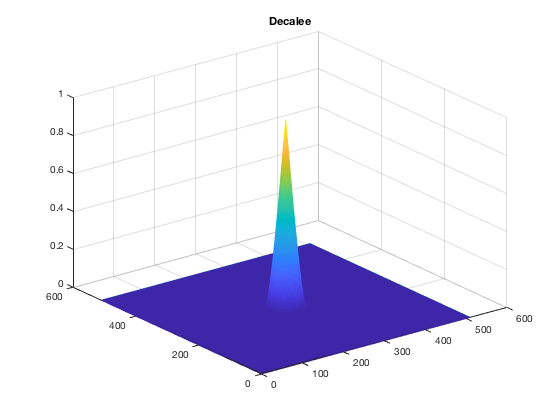

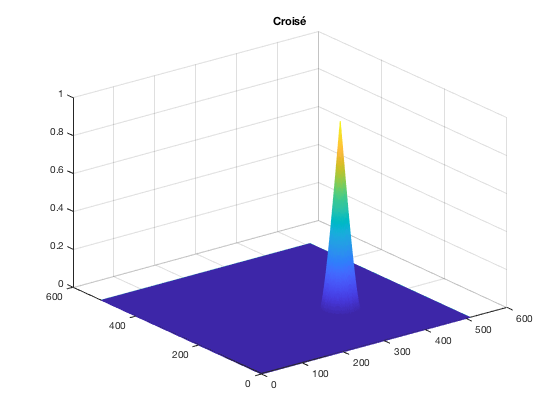

% Affichage des resultats avec meshz()


Regarder la taille de ICroiseCorr, faire l'analogie avec la convolution vue dans la partie 1.

A l'aide de la fonction find() relever la position du maximum de la matrice ICroiseCorr

Calculer la distance de cette position au centre de l'image 

Les comparer au décalages introduits entre Itest et ItestDecale puis conclure quand à la corrélation croisée entre 2 images

## Question 6

### Repérer la position des croix grace à la corrélation croisée de l'image . Pour cela :

Ouvrir pour comprendre la fonction "MettreCroix" puis positionner 5 croix arbitrairement sur une nouvelle image ICroix (256 x 256) 

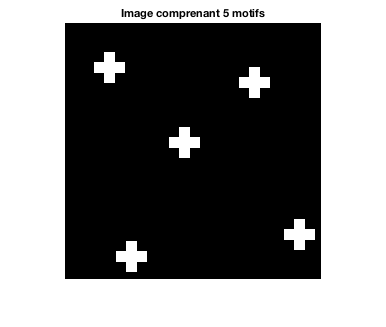

% Ajouts successifs de croix sur l'image ICroix de taile 256x256

% Affichage de ICroix


Extraire le motif de croix de largeur 31x31 et le stocker dans Motif

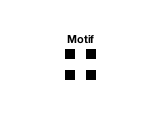

% extraction

% affichage du motif ac imshow()


Calcul de la corrélation croisée , 

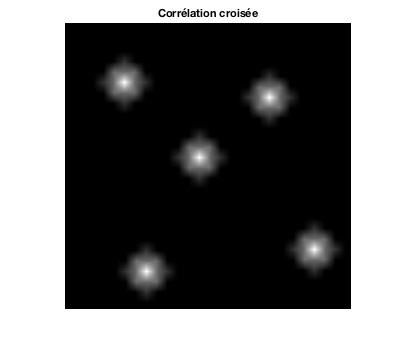

% Calcul de la corrélation croisée de ICroix et Motif à l'aide de xcorr(2),

% Normalisation de la corrélation

% Affichage des résultats 


Reacadrer l'image de corrélation sur les 256 pixels centraux puis, à l'aide de la fonction find() relever la position des maximums de la matrice Corr

%prise des 256 pixels centraux

% utiliation de find() pour stocker les positions des maximums


Ajouter un marker à l'aide de insertMarker() sur les positions trouvées puis afficher les prédiction sur l'image ICroix

Vérifier que les marqueurs sont bien positionnés au centre des motifs de croix.